## ***Initialize***

close all;  
clear;
clc;

strPath = fullfile(cd(), 'filter');
addpath(strPath);

strPath = fullfile(cd(), 'estimator');
addpath(strPath);

strPath = fullfile(cd(), 'sensor_data_maker');
addpath(strPath);

strPath = fullfile(cd(), 'visualize_result');
addpath(strPath);

## *Make IMU Data*

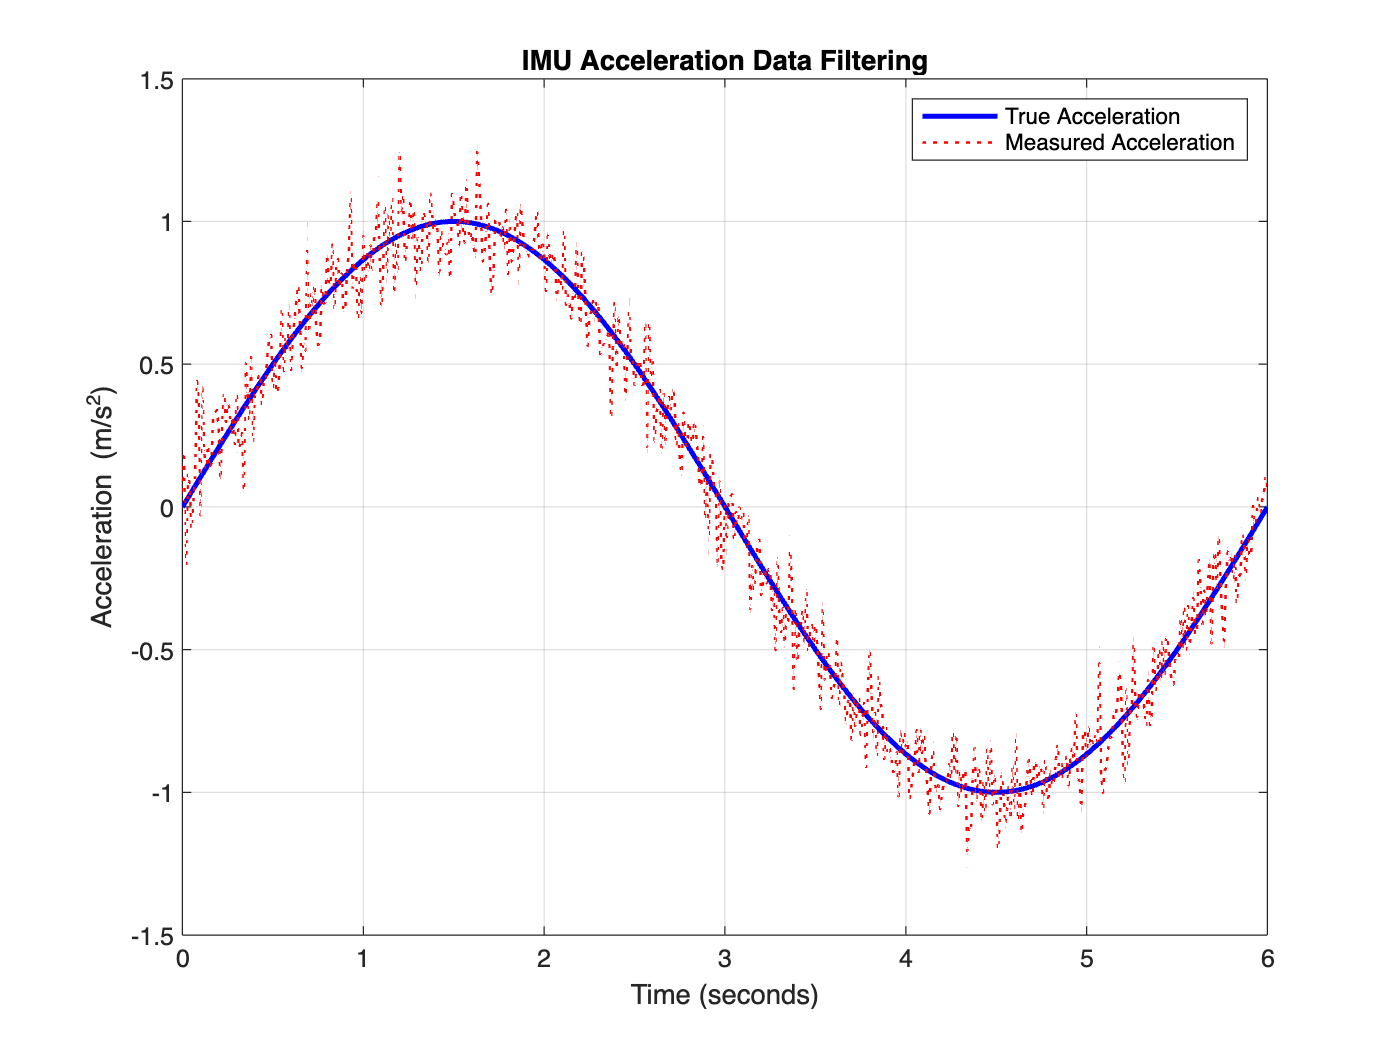

end_of_time = 6; % seconds, total time measured
sampling_frequency = 100; % hz, sampling frequency
noise_std = 0.1; % m/s2, standard deviation of noise
[gt_acceleration_data, imu_data, imu_measure_time] = makeIMUData(end_of_time, sampling_frequency, noise_std);

## Average Filter

Error: 0.572


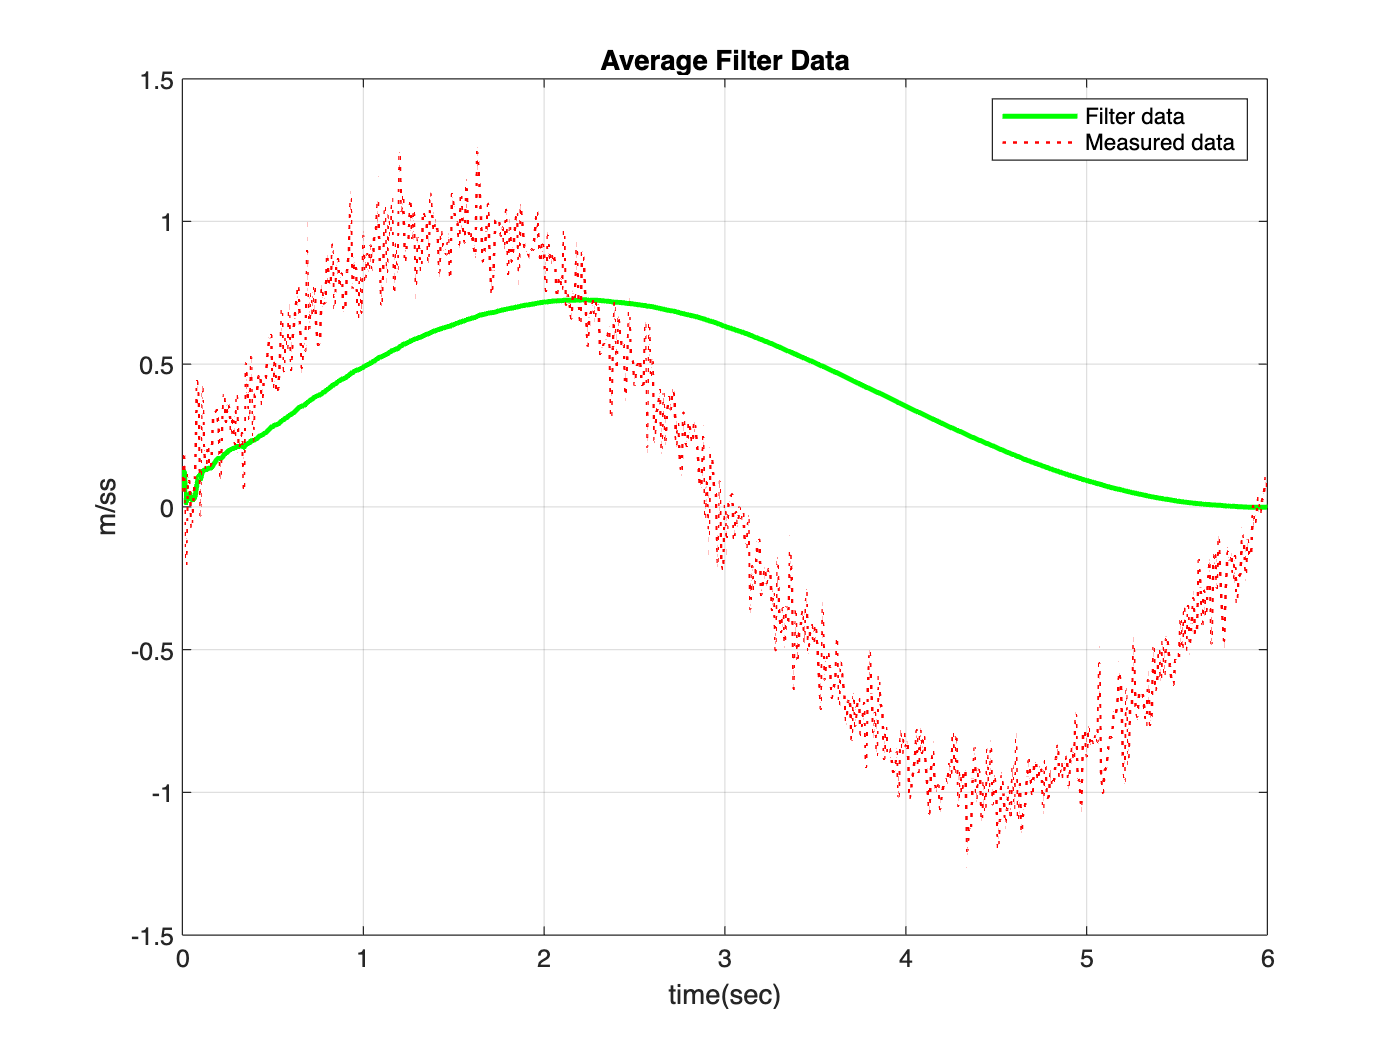

[imu_average_filter_data] = averageFilter(imu_data, imu_measure_time, gt_acceleration_data, 'IMU'); % sensor type: 'Encoder', 'IMU'

## Moving Average Filter

Error: 0.036


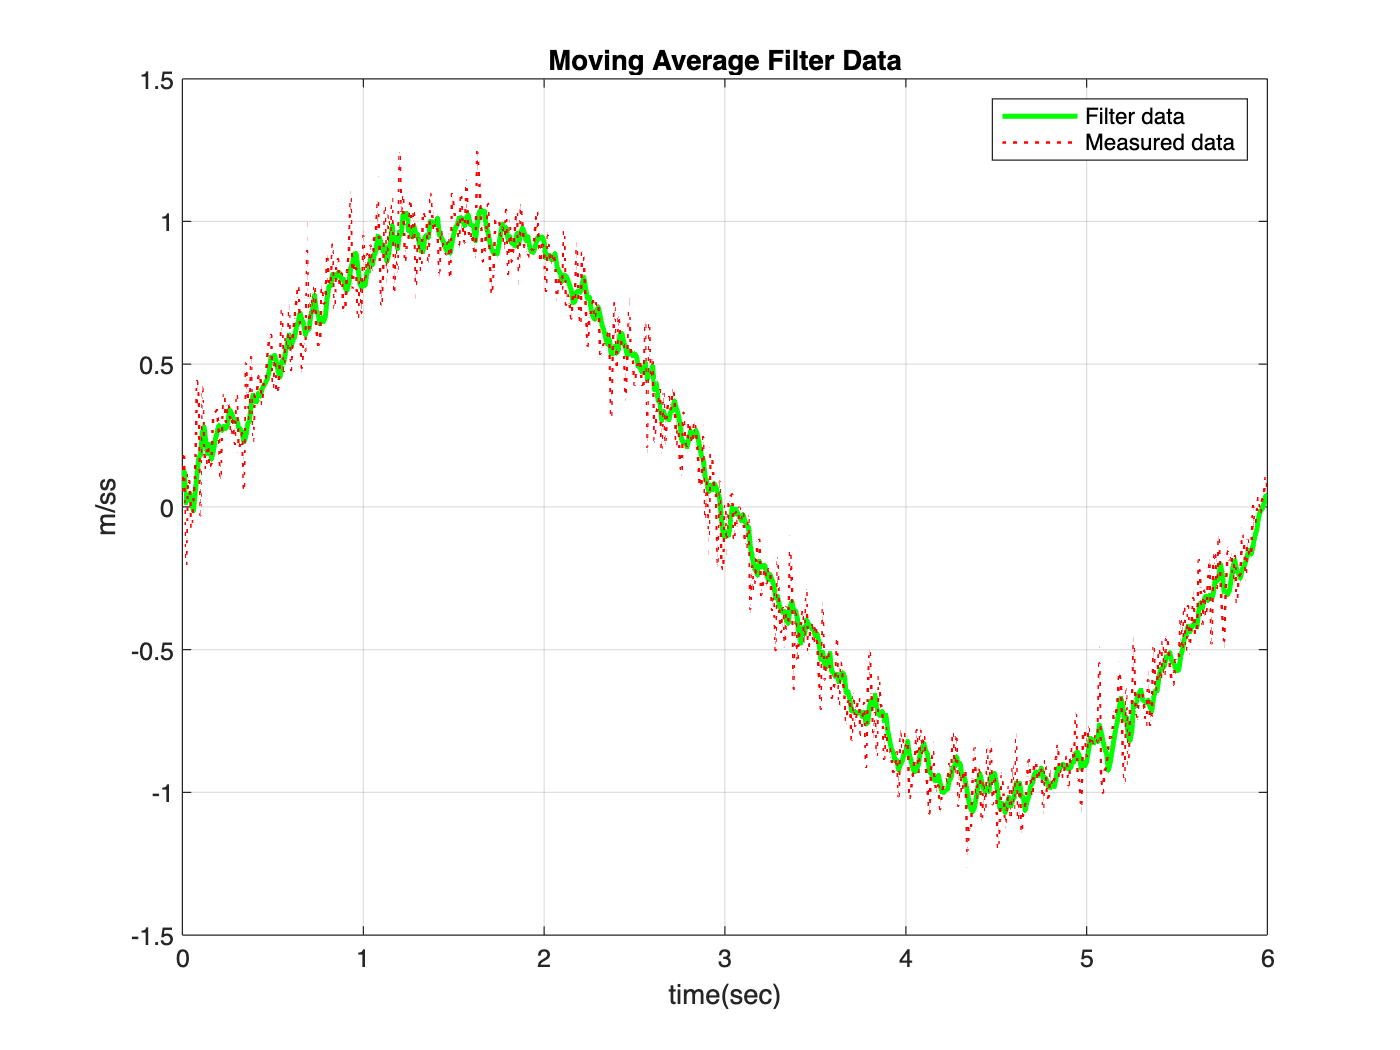

window_size = 5; % how many data will you use, try changing the values in various way
[imu_moving_average_filter_data] = movingAverageFilter(imu_data, imu_measure_time, gt_acceleration_data, window_size, 'IMU'); % sensor type: 'Encoder', 'IMU'

## Exponential Moving Average Filter

Error: 0.054


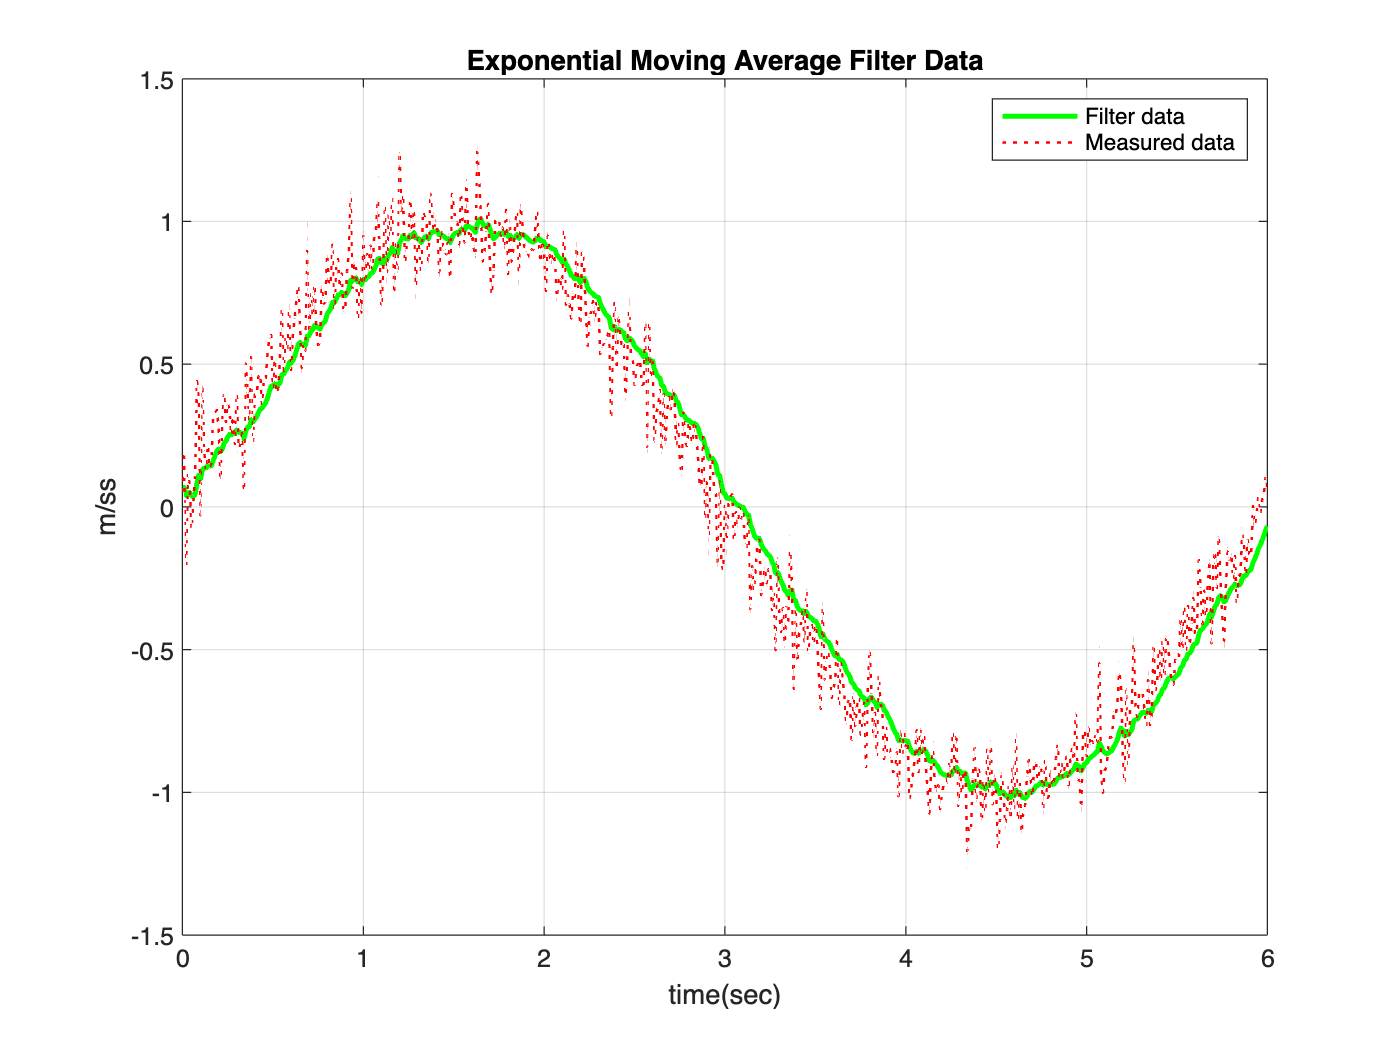

alpha = 0.9; % how much weight do you give to current data, try changing the values in various way
[imu_exponenital_moving_average_filter_data] = exponentialMovingAverageFilter(imu_data, imu_measure_time, gt_acceleration_data, alpha, 'IMU'); % sensor type: 'Encoder', 'IMU'

## Matlab Low Pass Filter

Error: 0.040


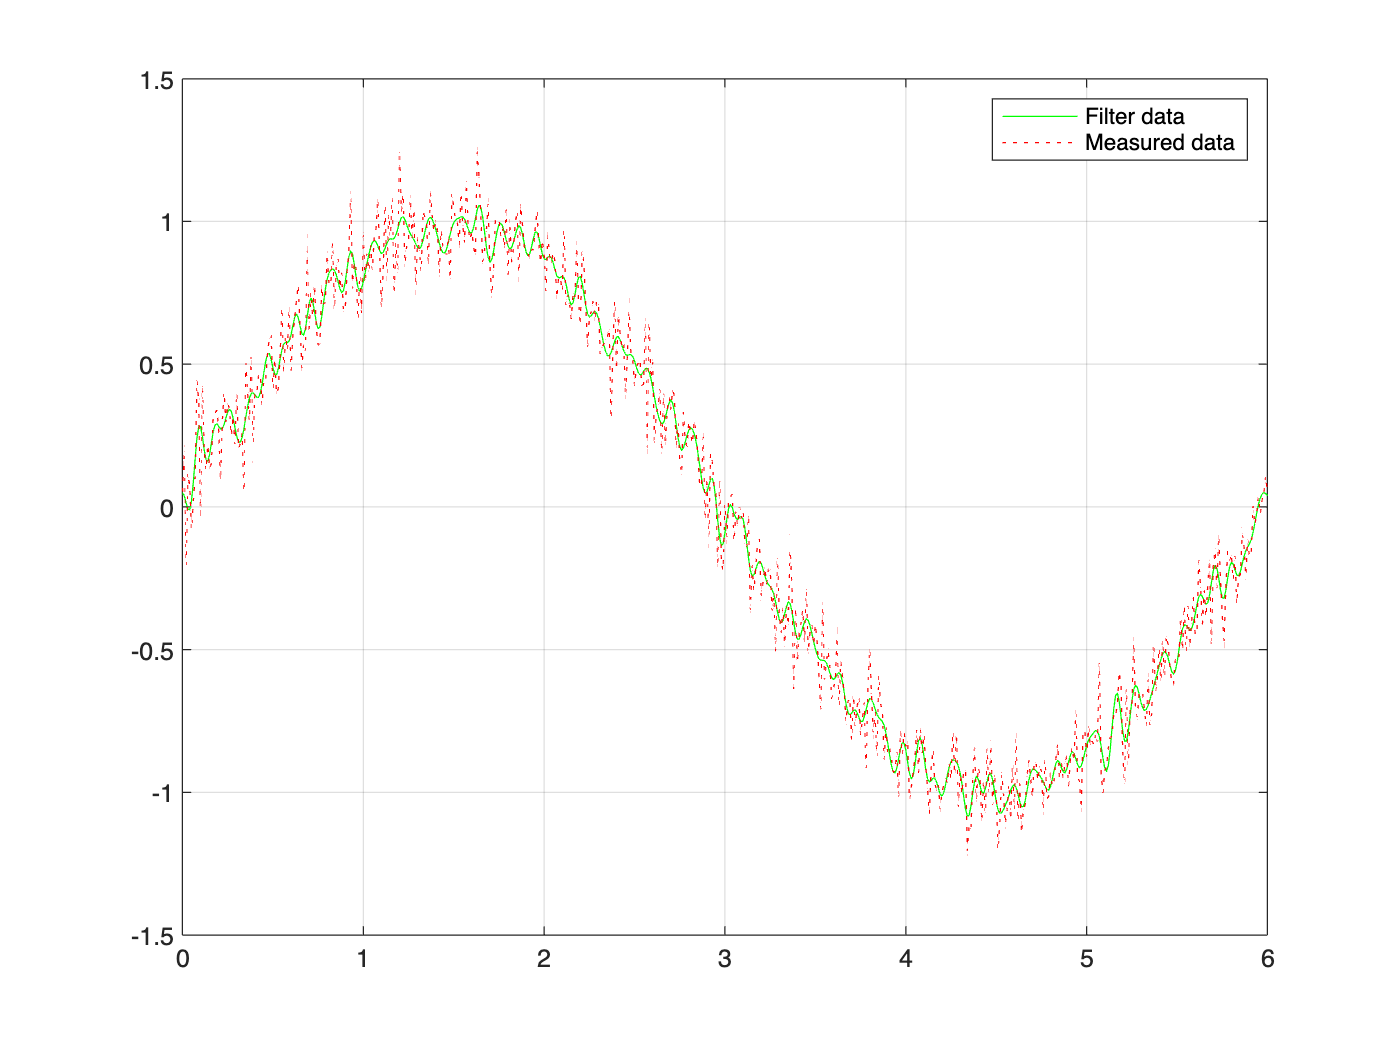

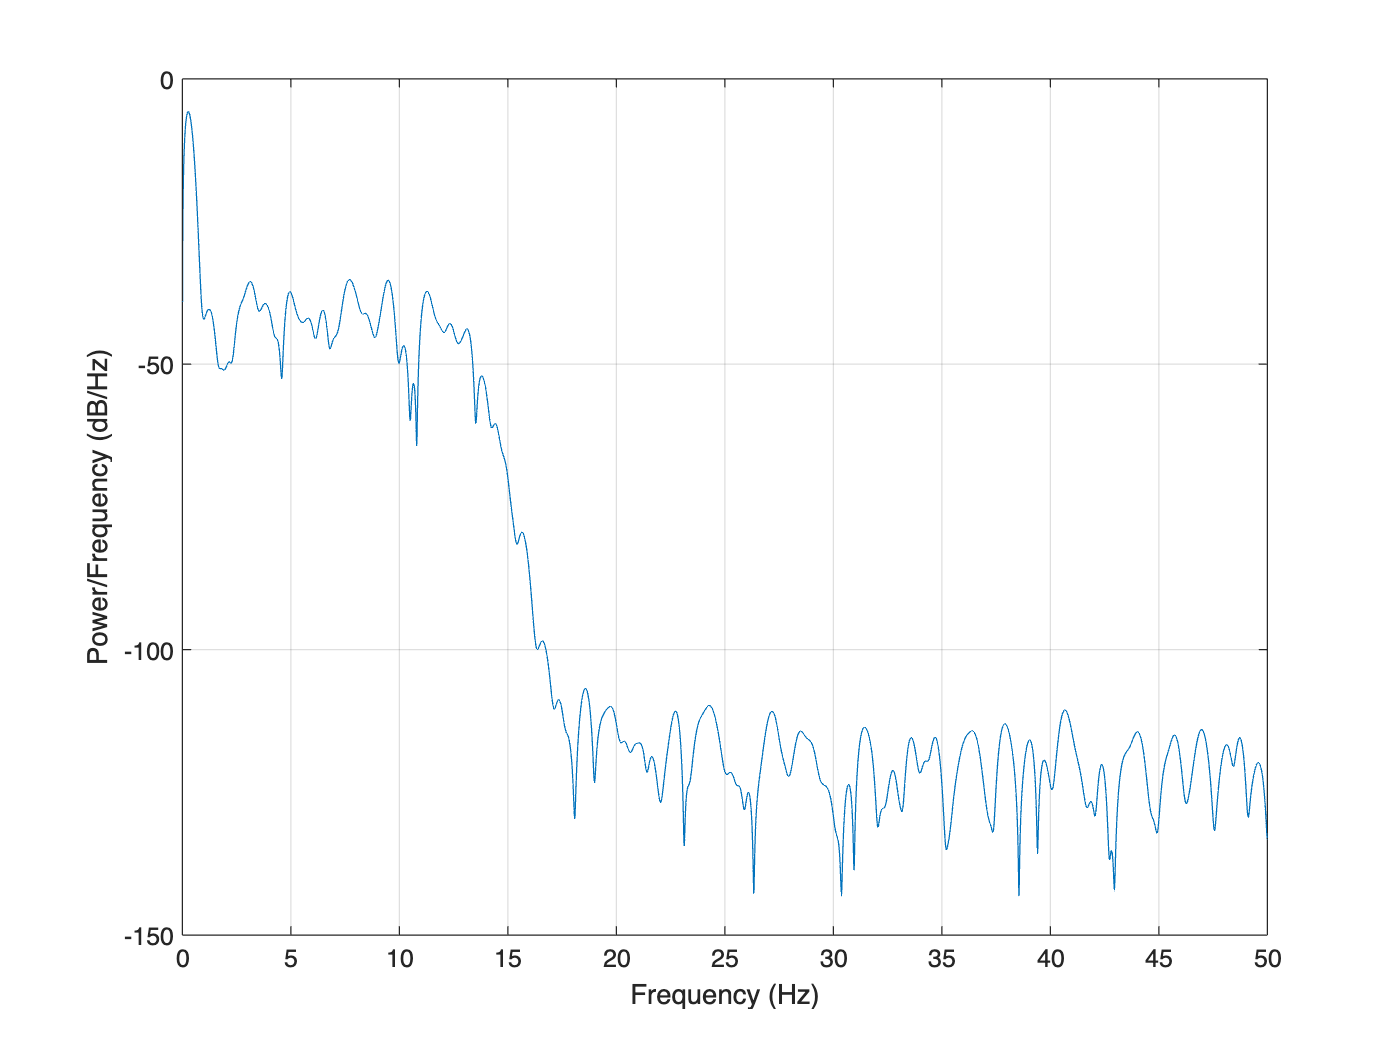

sampling_frequency = 100;
cut_off_frequency = 10; % Hz, try changing the values in various way

imu_low_pass_filter_data = lowpass(imu_data, cut_off_frequency, sampling_frequency);

visualizeLowPassFilterData(imu_measure_time,imu_low_pass_filter_data,imu_data,gt_acceleration_data, sampling_frequency);

## Visualize Filter Result - IMU

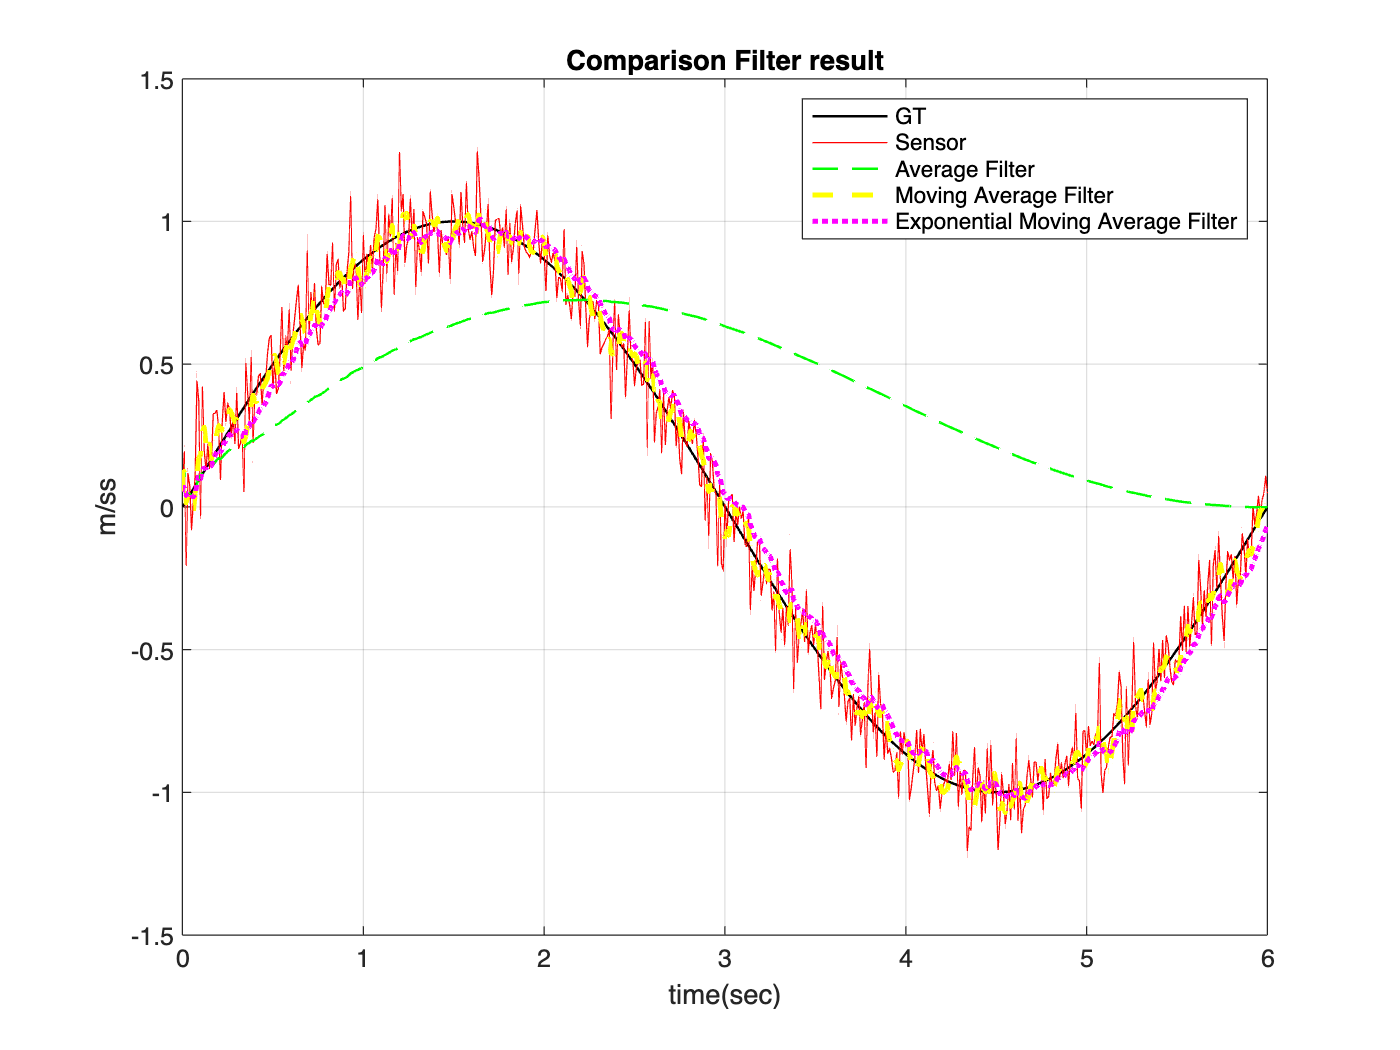

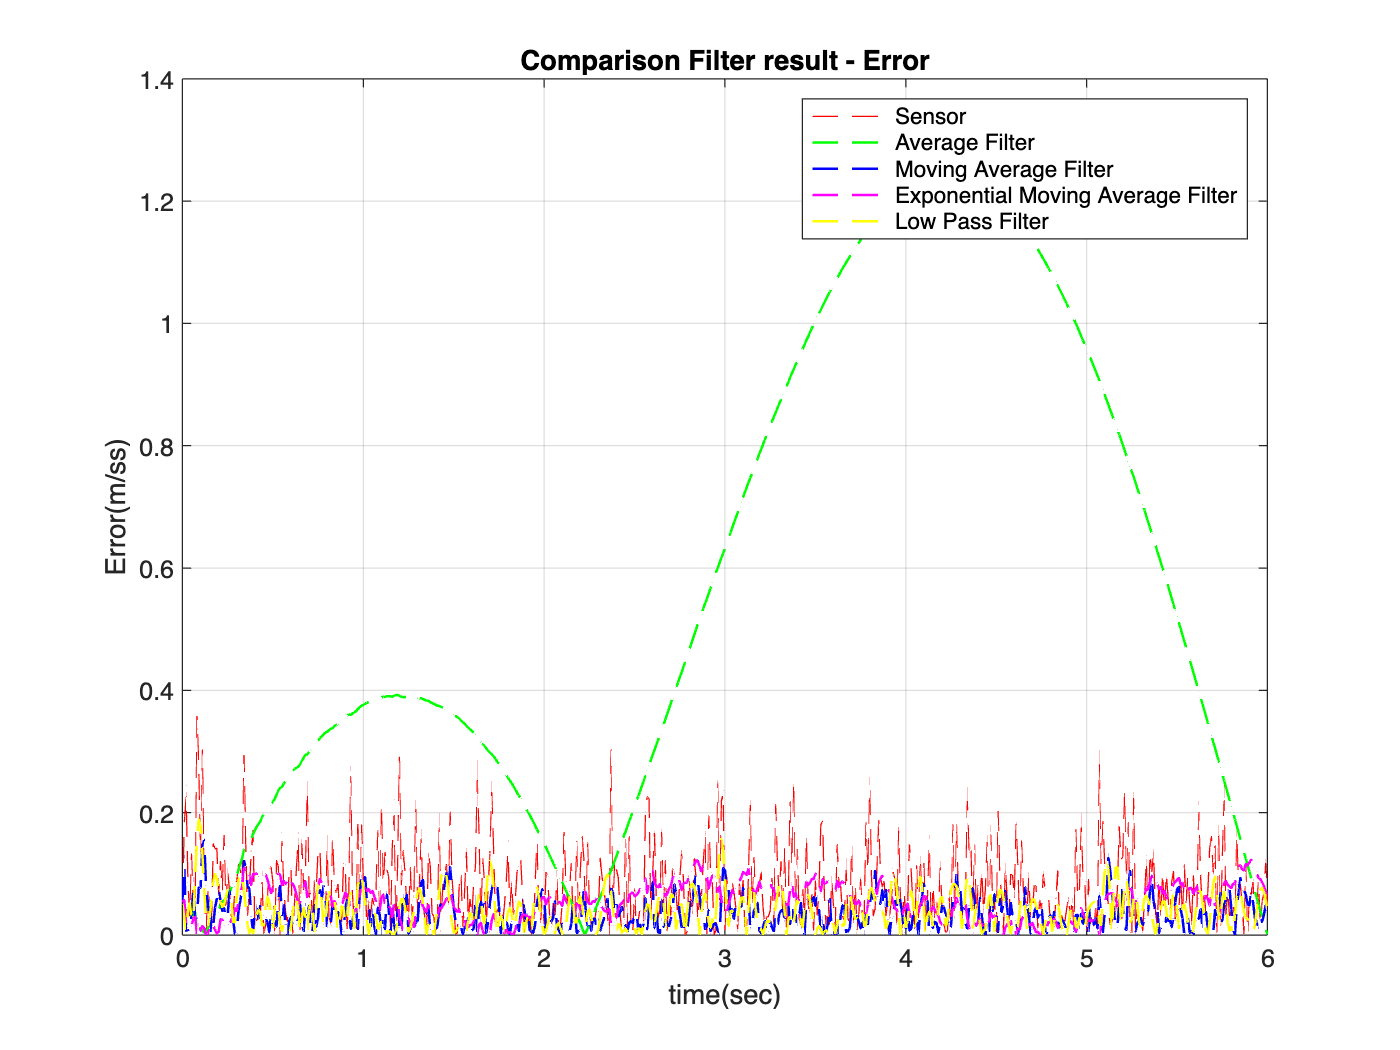

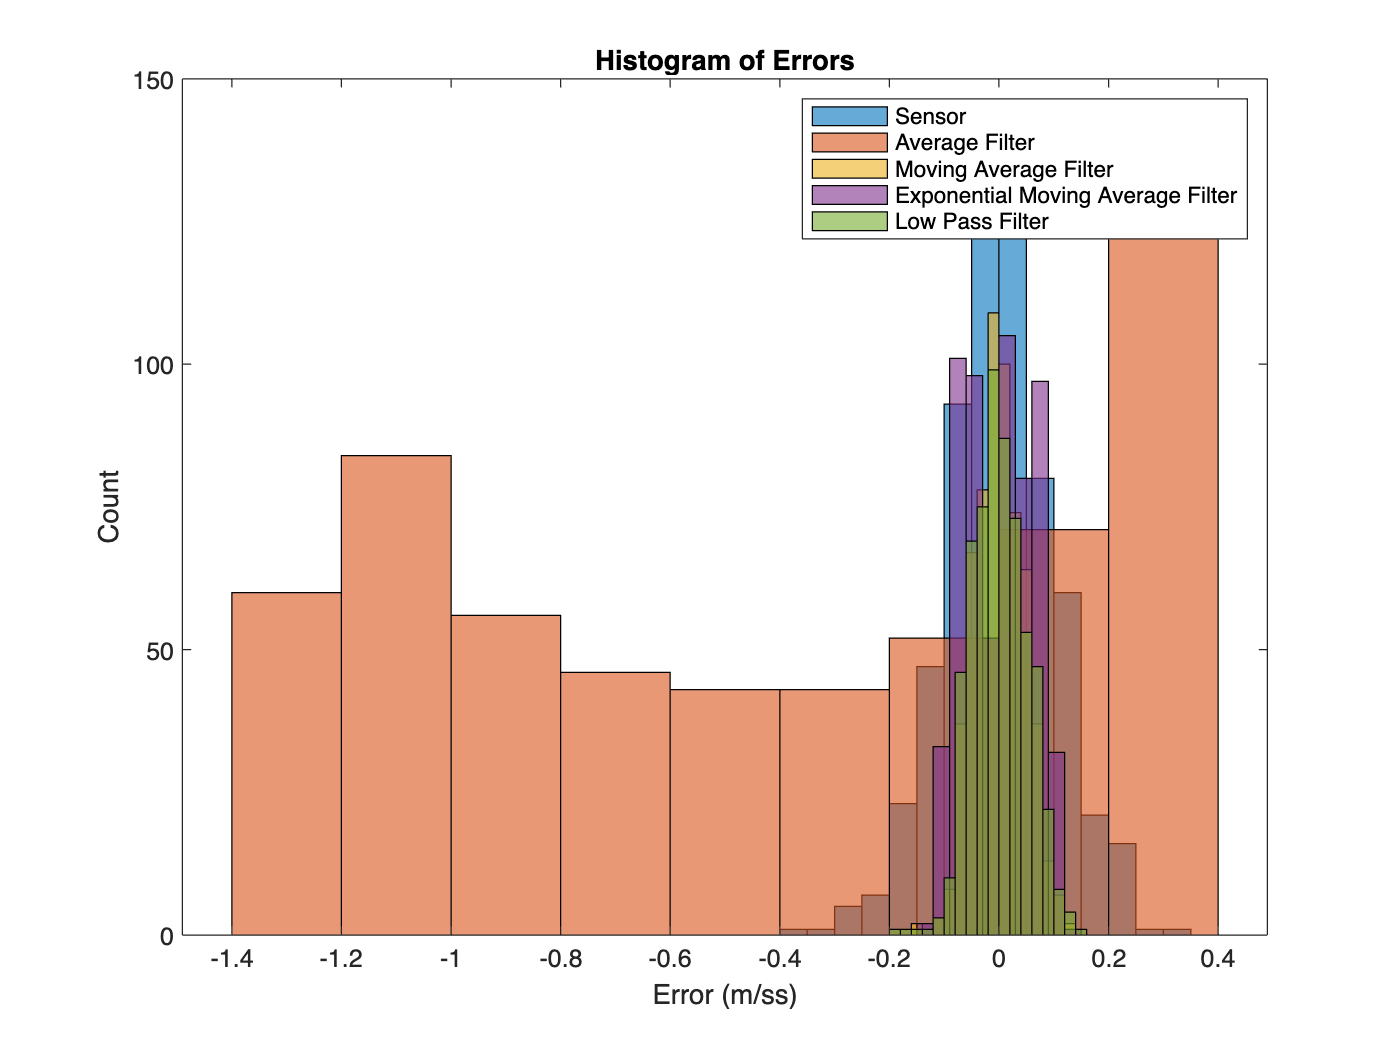

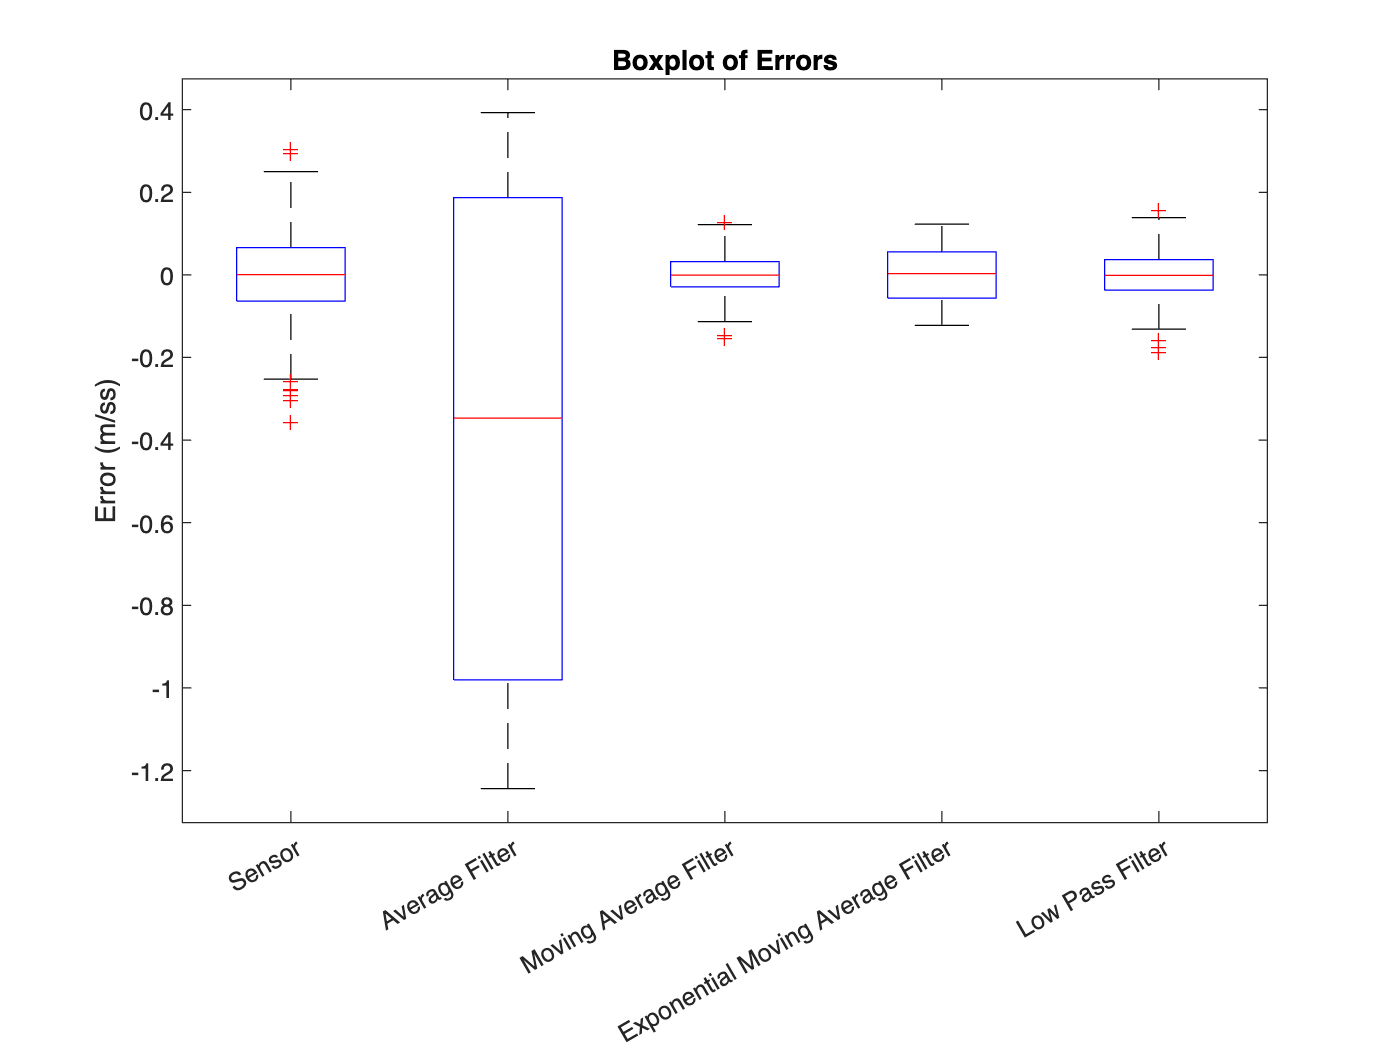

visualizeIMUFilterData(gt_acceleration_data, imu_data, imu_measure_time, imu_average_filter_data, imu_moving_average_filter_data, imu_exponenital_moving_average_filter_data, imu_low_pass_filter_data);

## Calculate Wheel Speed Using Encoder Data

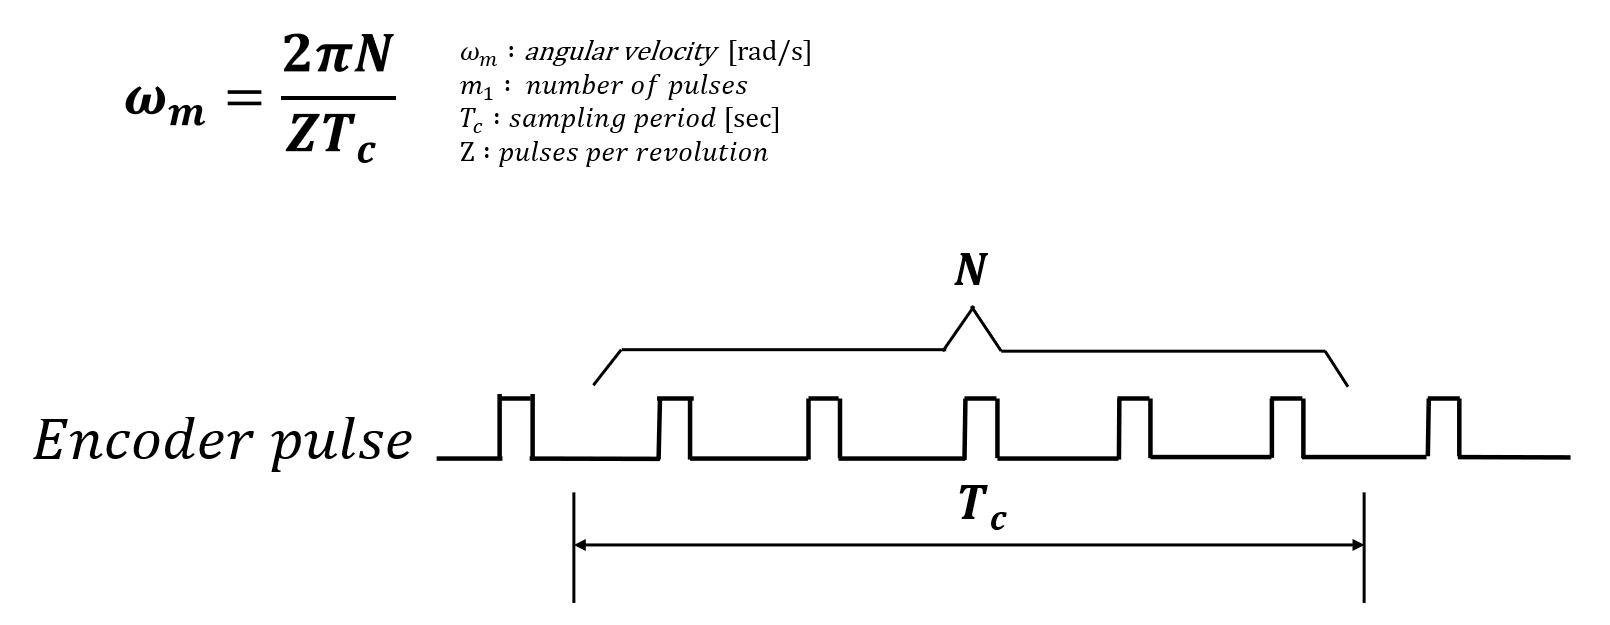

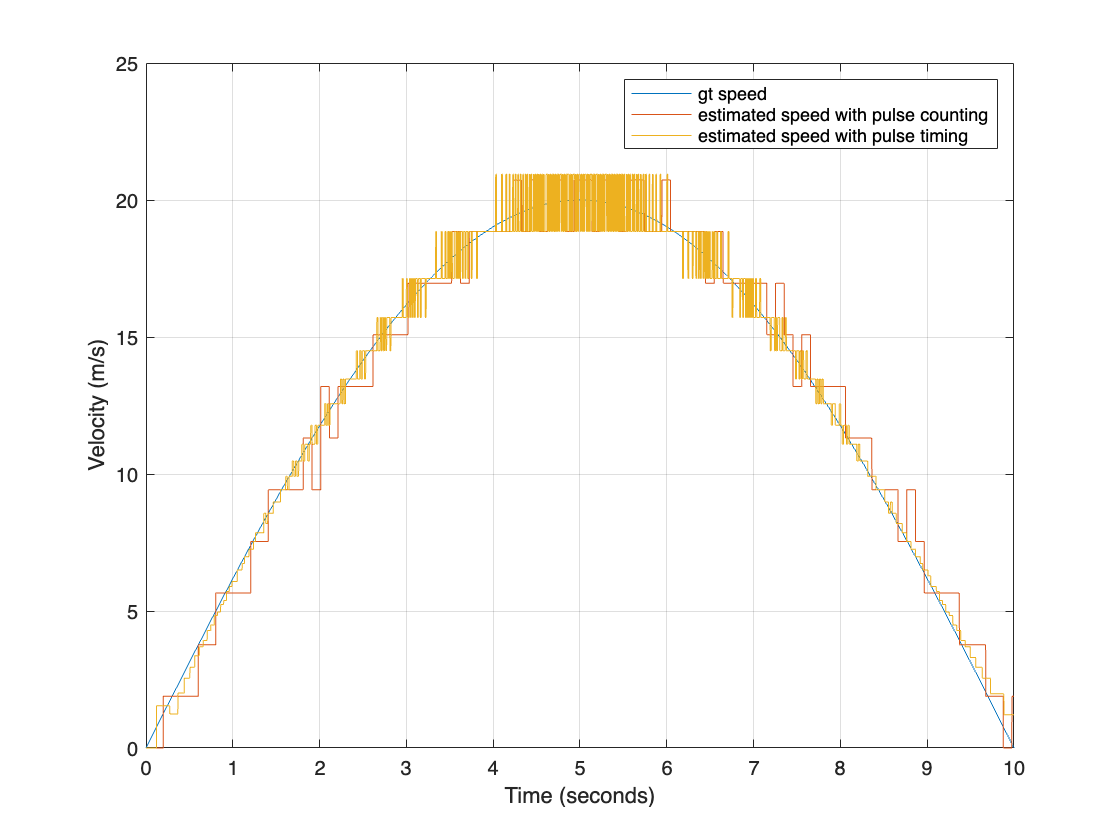

% parameter setting
wheelRadius = 0.6; % wheel diameter (m)
pulsesPerRevolution = 20; % number of pulses per revolution of the wheel

load("pulses_data.mat");

% speed estimation with pulse signal
time_interval = 0.1; % seconds
AngularVelocityPulseCounting = PulseCountingMethod(t, pulses, pulsesPerRevolution, time_interval);
AngularVelocityPulseTiming = PulseTimingMethod(t, pulses, pulsesPerRevolution);

estimatedSpeedWithPulseCounting = wheelRadius * AngularVelocityPulseCounting;
estimatedSpeedWithPulseTiming = wheelRadius * AngularVelocityPulseTiming;

% visualize real speed and estimated speed
visualizeEncoderSpeed(t, gtVel_ms, estimatedSpeedWithPulseCounting, estimatedSpeedWithPulseTiming);